## **System + data**

% Define system components
oqpskmod = comm.OQPSKModulator('BitInput', true);
oqpskdemod = comm.OQPSKDemodulator('BitOutput', true);
channel = comm.AWGNChannel('EbNo', 10, 'BitsPerSymbol', 2);
errorRate = comm.ErrorRate("ReceiveDelay", 4);

span = 4;                 % Filter span (number of symbols)
samplesPerSymbol = 8;      % Samples per symbol
decimation=4;
sps = samplesPerSymbol/decimation;
rolloff = 0.35;               % Rolloff factor

txFilter = comm.RaisedCosineTransmitFilter( ...
    'Shape','Square root',...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'OutputSamplesPerSymbol', samplesPerSymbol);

rxFilter = comm.RaisedCosineReceiveFilter( ...
    'Shape','Square root',...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'InputSamplesPerSymbol', samplesPerSymbol, ...
    'DecimationFactor', decimation);

symbolSync = comm.SymbolSynchronizer(...
    'SamplesPerSymbol', sps, ...
    'Modulation','OQPSK', ...
    'TimingErrorDetector','Gardner (non-data-aided)');

% Frame setup
numFrames = 12;             % Number of frames to transmit
frameSize = 2^8;        % Size of payload (in bits) per frame
preambleLength = 7;         % Barker code length
barkerGen = comm.BarkerCode("Length", preambleLength, 'SamplesPerFrame', preambleLength);
barkerCode = (barkerGen() + 1) / 2; % Map [-1, 1] to [0, 1]

% Generate multiple frames
txData = [];
for frameIdx = 1:numFrames
    % Generate payload for this frame
    payload = randi([0 1], frameSize, 1);

    % Create frame: [preamble | payload]
    frame = [barkerCode; payload];
    txData = [txData; frame]; %#ok<AGROW>
end

## Transmitter

% Modulate the signal
txSignal = oqpskmod(txData);

% Filter the signal at the transmitter (with upsampling)
txSignal = txFilter(txSignal);

## Receiver

% Pass the signal through the AWGN channel
rxSignal = channel(txSignal);

% Timing Offset
vfd = dsp.VariableFractionalDelay; cd = comm.ConstellationDiagram;
tau=0.5;
rxSignal=vfd(rxSignal,tau);

% Filter the signal at the Receiver (with downsampling)
rxSignal = rxFilter(rxSignal); 

% for index = 0:500
%     % Delay signal
%     tau_hat = index/500; 
%     delayedsig = vfd(rxSignal, tau_hat);
%     % Visualize constellation
%     cd(delayedsig); pause(0.1);
% end

% Apply symbol synchronization
rx_I_sync = real(symbolSync(real(rxSignal)));
rx_Q_sync = real(symbolSync(imag(rxSignal)));
minLength = min(length(rx_I_sync), length(rx_Q_sync));
rx_I_sync = rx_I_sync(1:minLength);
rx_Q_sync = rx_Q_sync(1:minLength);

rxSignal = rx_I_sync + 1j*rx_Q_sync;

### Symbol-Synchronize and Time Correction

rxData = oqpskdemod(rxSignal);
errorStats = errorRate(txData,rxData);
disp(["BER: ", errorStats(1)]);

    "BER: "    "0"



### Frame-Synchronize

# Time-Series

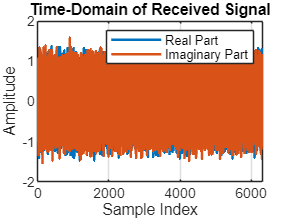

figure;
plot(real(rxSignal), 'LineWidth', 1.5,'DisplayName','Real Part');
hold on;
plot(imag(rxSignal), 'LineWidth', 1.5,'DisplayName','Imaginary Part');
title('Time-Domain of Received Signal');
xlabel('Sample Index');
ylabel('Amplitude');
legend();
grid on;
hold off;

# PSD

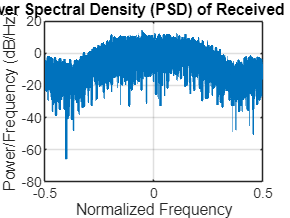

figure;
[psdValues, psdFreq] = periodogram(rxSignal, [], [], 1, 'centered');
plot(psdFreq, 10*log10(psdValues), 'LineWidth', 1.5);
title('Power Spectral Density (PSD) of Received Signal');
xlabel('Normalized Frequency');
ylabel('Power/Frequency (dB/Hz)');
grid on;

# Constellation

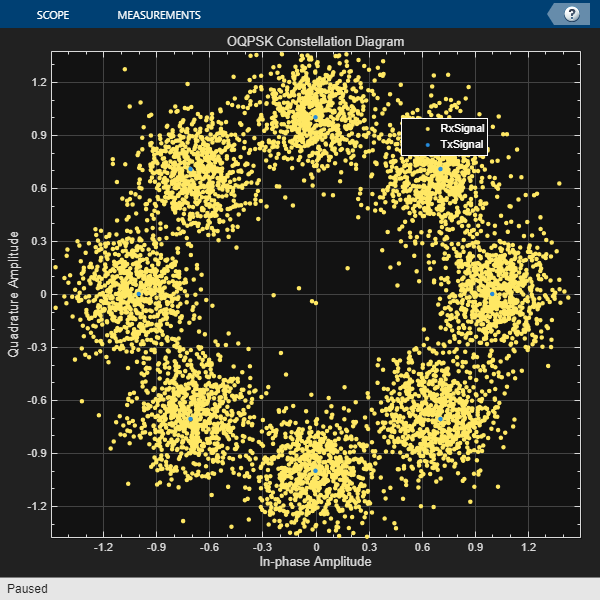

% Create a Constellation Diagram object
constDiagram = comm.ConstellationDiagram( ...
    'ReferenceConstellation', 0, ...
    'NumInputPorts', 2, ...
    'ShowLegend', true, ...
    'Title', 'OQPSK Constellation Diagram', ...
    'ChannelNames', {'RxSignal', 'TxSignal'});

% Visualize rxSignal and txSignal in the constellation diagram
constDiagram(rxSignal, oqpskmod(txData));

# Eye-Diagram

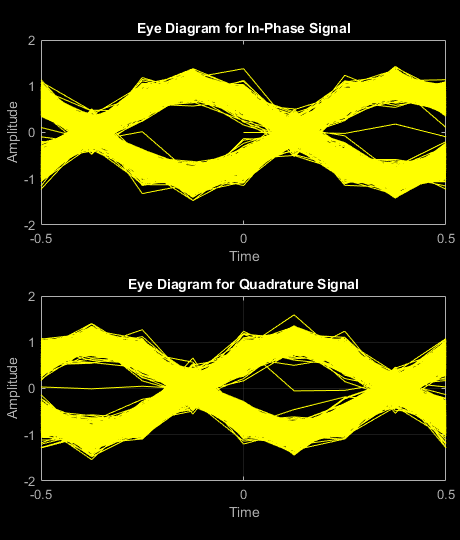

figure;
eyediagram(rxSignal, samplesPerSymbol);
%eyediagram(oqpskmod(txData), samplesPerSymbol);
xlabel('Time');
ylabel('Amplitude');
grid on;